We will define a synthetic case of transitional propebility

clear all
P = [.8 .1 .1; .3 .6 .1; .2 .2 .6]

P =     0.8000    0.1000    0.1000
    0.3000    0.6000    0.1000
    0.2000    0.2000    0.6000


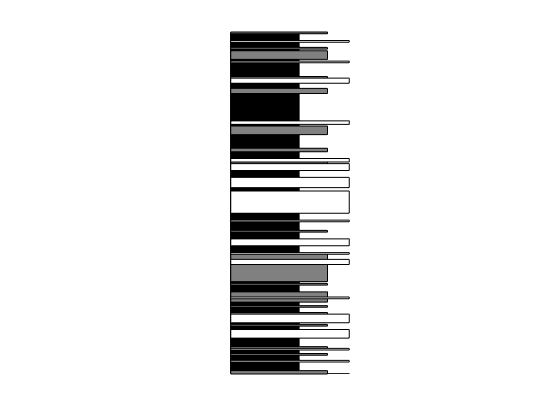

v = [0 1 0];
colors = gray(numel(v));

nLayers = 200;
nSections = 1;
figure('Color', 'White')

result = zeros(nLayers, nSections);
for j = 1:nSections
subplot(1,nSections,j)
for i =1:nLayers
    v = v * P;
    cdfVector = cumsum(v);
    rndValue = rand(1,1);
    sample = find(rndValue <= cdfVector,1);
    v =  zeros(1,numel(v));
    v(sample) = 1;
    result(i,j) = sample;
end
    [intervalData] = thickness2interval(result(:,j), true);
    plotIntervalTable(intervalData);
end

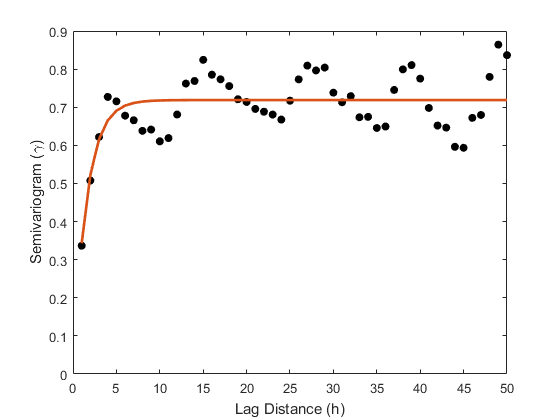



[h, gamma] = variogram1d(result(:,end)); hold on;
[b,fval,exitflag,output, gammaFit] = fitvariogram(gamma, h, 'e');
plot(h, gammaFit, 'LineWidth', 2);

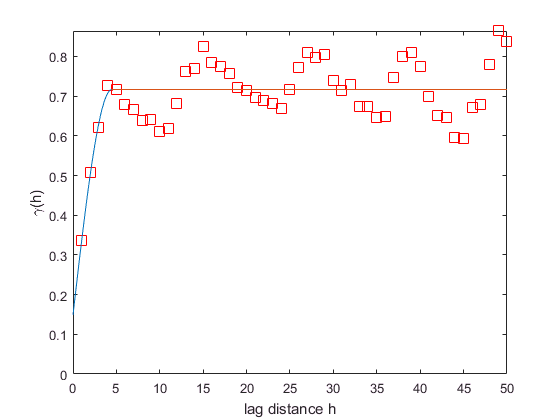



figure
    a0 = 15; % initial value: range 
    c0 = 0.1; % initial value: sill 
    [a,c,n] = variogramfit(h,gamma,a0,c0,[],...
                           'solver','fminsearchbnd',...
                           'nugget',0,...
                           'plotit',true);

## Upscaling 

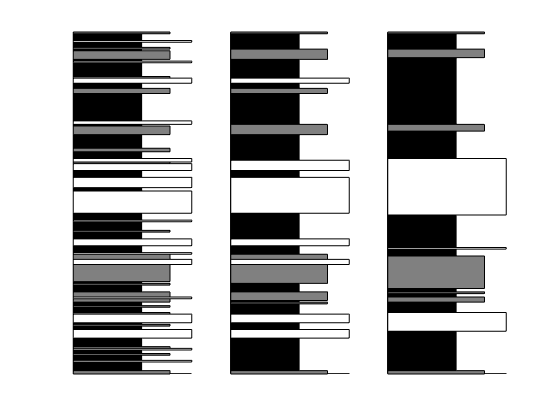

classification = result(:,end);
smoothingIntervals = [1 5 11];

figure('Color', 'White')
for i = 1:numel(smoothingIntervals)
    padSize = (smoothingIntervals(i) - 1) / 2;
    subplot(1,numel(smoothingIntervals),i)
    classification = result(:,end);
    
    B = padarray(classification,padSize,'replicate');
    for j = 1+padSize:padSize+numel(classification)
        classification(j-padSize) = mode(B(j-padSize: j+padSize));
    end
    
    [intervalData] = thickness2interval(classification, true);
    plotIntervalTable(intervalData);
end
plotIntervalTable(intervalData);

## Analysis to get back the probablity function

classification = result(:,end);
allClasses = unique(classification);
nClasses = numel(allClasses);

transition = [classification(1:end-1) classification(2:end)];
nTransitions = size(transition,1);

classesVector = (1:nClasses)';
combinations = [combnk(classesVector,2); fliplr(combnk(classesVector,2));...
    classesVector classesVector];

for i = 1:size(combinations,1)
   instances = ismember(transition, combinations(i,:),'rows');   
   Pestimated(combinations(i,1), combinations(i,2)) = sum(instances);
end
Pestimated = Pestimated ./ repmat(sum(Pestimated,2),1,nClasses)

Pestimated =     0.7400    0.1300    0.1300
    0.3333    0.5778    0.0889
    0.2037    0.1111    0.6852



% Calculate back-directional markov chain
for i = 1:size(combinations,1)
   instances = ismember(fliplr(transition), combinations(i,:),'rows');   
   PestimatedBack(combinations(i,1), combinations(i,2)) = sum(instances);
end
PestimatedBack = PestimatedBack ./ repmat(sum(PestimatedBack,2),1,nClasses)

PestimatedBack =     0.7400    0.1500    0.1100
    0.2889    0.5778    0.1333
    0.2407    0.0741    0.6852


nLayers = 100;
newLayer = 2;
nSections = 3;

pNewLayers = normr(rand(nLayers,nClasses));
[~,seq] = max(pNewLayers,[],2);


## Update the Prop. (Initial way)... does not satisify the transilitional probablity

UQ Discussion:

- Techniques + liscence

- Monte carlo (parallal computing) but without multiple liscences

- if developed internally + how to deploy.

- Software design and book-keeping of UQ data

- Computationally intensive and time consuming

- "Have to give the managment a number" + UQ is hard to understand ==> wrap it in a business plan

- we do uncerntainty study but we don't know the decision.

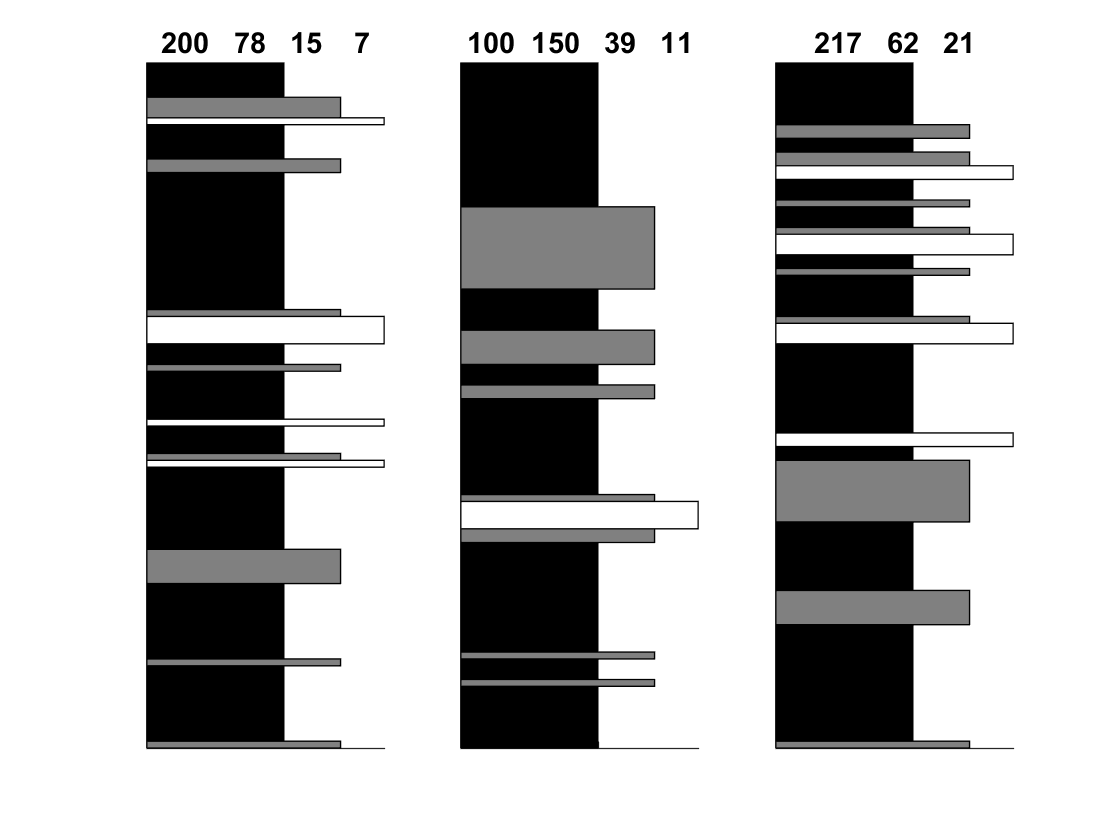


nLayers = 100;
newLayer = 2;
nSections = 3;

pNewLayers = repmat([.45 .3 .25], nLayers, 1);
%pNewLayers = normr(rand(nLayers,nClasses));

result = zeros(nLayers,nSections);

figure('Color', 'White')
for j = 1:nSections
subplot(1,nSections,j)
for i =1:nLayers
    oldLayer = newLayer;
    pPrior = Pestimated(oldLayer,:);
    pNewLayer = pNewLayers(i,:);
    P = (pNewLayer .* pPrior) ./ sum(pNewLayer .* pPrior);
    cdfVector = cumsum(P);
    rndValue = rand(1,1);
    newLayer = find(rndValue <= cdfVector,1);
    result(i,j) = newLayer;
end
    [intervalData] = thickness2interval(result(:,j), true);
    plotIntervalTable(intervalData);
    title(num2str(histcounts(result)));
end

## Simulation with  backward Markov Chain

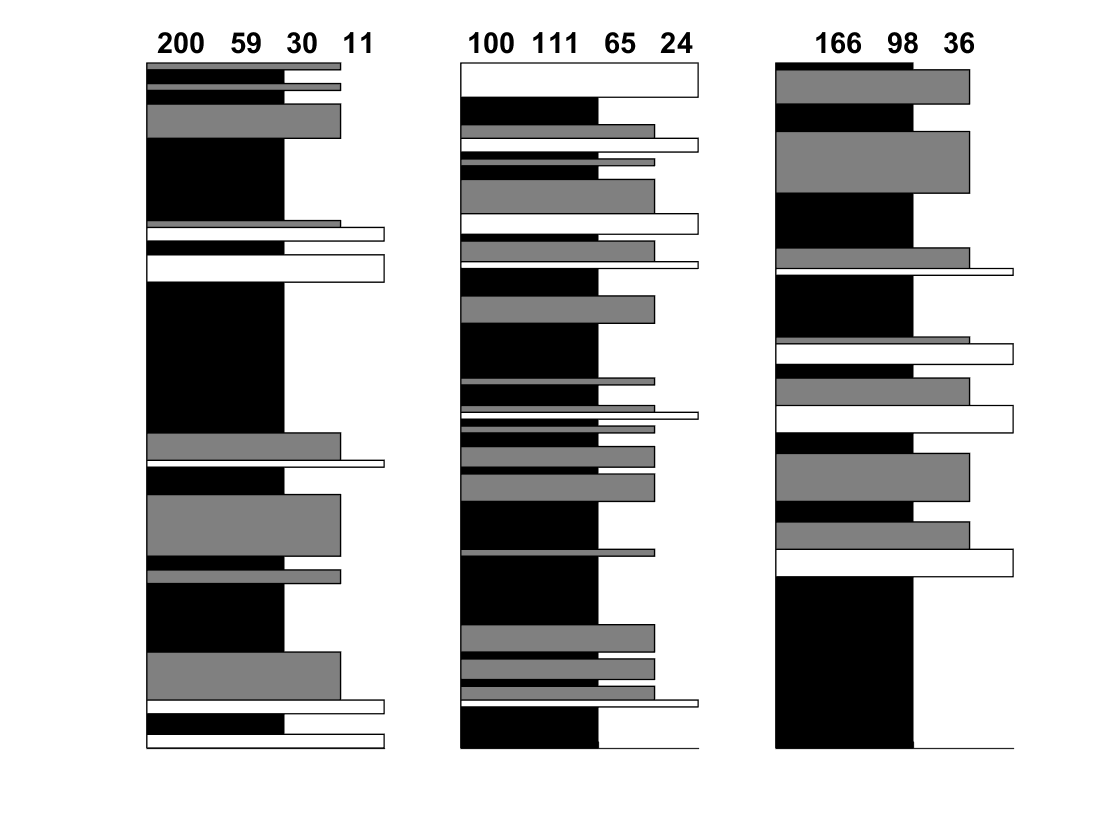

nLayers = 100;
newLayer = 2;
nSections = 3;

pNewLayers = repmat([.45 .3 .25], nLayers, 1);
pNewLayers = repmat([.333 .333 .333], nLayers, 1);

%pNewLayers = normr(rand(nLayers,nClasses));

result = zeros(nLayers,nSections);

figure('Color', 'White')
for j = 1:nSections
    %x = normr([.45 .3 .25] - (1:3).^j / 180);
    %pNewLayers = repmat(x, nLayers, 1);
subplot(1,nSections,j)
for i =nLayers:-1:1
    oldLayer = newLayer;
    pPrior = PestimatedBack(oldLayer,:);
    pNewLayer = pNewLayers(i,:);
    P = (pNewLayer .* pPrior) ./ sum(pNewLayer .* pPrior);
    cdfVector = cumsum(P);
    rndValue = rand(1,1);
    newLayer = find(rndValue <= cdfVector,1);
    result(i,j) = newLayer;
end
    [intervalData] = thickness2interval(result(:,j), true);
    plotIntervalTable(intervalData);
    title(num2str(histcounts(result)));
end

## Test on (https://www.youtube.com/watch?v=jY2E6ExLxaw)

p_x = [.2 .8] %sad happy

p_x =     0.2000    0.8000


p_yGx = [.1 .3 .5 .1; .4 .4 .2 0] %w s c f

p_yGx =     0.1000    0.3000    0.5000    0.1000
    0.4000    0.4000    0.2000         0


x = 2; y = 1;
p_hGw = p_yGx(x,y) * p_x(x) / sum(p_yGx(:,y)' .* p_x)

p_hGw = 0.9412

## Test 2 on (https://www.youtube.com/watch?v=jY2E6ExLxaw) Transitional 21 minutes

labels = {'Sad', 'Happy'};
p_x = [.2 .8]; %sad happy
array2table(p_x, 'VariableName', labels)

ans =     Sad    Happy
    ___    _____

    0.8    0.1  


p_xGx = [.99 .01; .1 .9];
array2table(p_xGx, 'RowNames', labels,'VariableName', labels)

ans =              Sad     Happy
             ____    _____

    Sad      0.99    0.01 
    Happy     0.1     0.9 
